Part A: Script to find the best linear function that fits the (log W, log A) data in the least squares sense

W_data = [70; 75; 77; 80; 82; 84; 87; 90]; % Given weights
A_data = [2.10; 2.12; 2.15; 2.20; 2.22; 2.23; 2.26; 2.30]; % Given surface areas
m = numel(W_data);
log_W_data = log10(W_data);
log_A_data = log10(A_data);
B = [ones(m,1),log_W_data];
C = B\log_A_data;

fprintf('The best linear function that fits the (logW, logA)')

The best linear function that fits the (logW, logA)

fprintf('data in the least squares sense is:')

data in the least squares sense is:

fprintf('    logA = %g + %g*logW',C(1),C(2))

    logA = -0.382068 + 0.379911*logW

Part B -- Predicted the surface area for a 95-kg person with height 180 cm is: 2.3404 (m^2)

log_A_estimate = C(1)+C(2)*log10(95);
A_estimate = 10 ^ log_A_estimate

A_estimate =    2.340408070385052


Part C: Plot the (log W, log A) data and the best fitting line

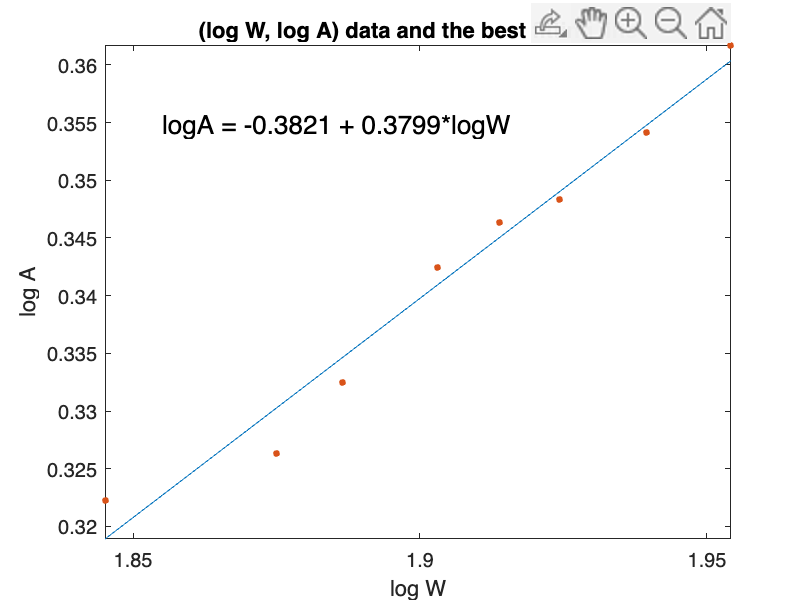

figure(1)
fplot(@(log_W) C(1)+C(2).*log_W)
hold on
plot(log_W_data, log_A_data, '.', 'markersize', 10)
xlim([log_W_data(1),log_W_data(m)]);
title('(log W, log A) data and the best fitting line');
xlabel('log W'); ylabel('log A');
text(1.855,0.355,'logA = -0.3821 + 0.3799*logW', 'fontsize',13);
hold off

Part D: Plot the (W, A) data and the function A = a*W^b

figure (2)
a = 10^C(1)

a =    0.414888925518295


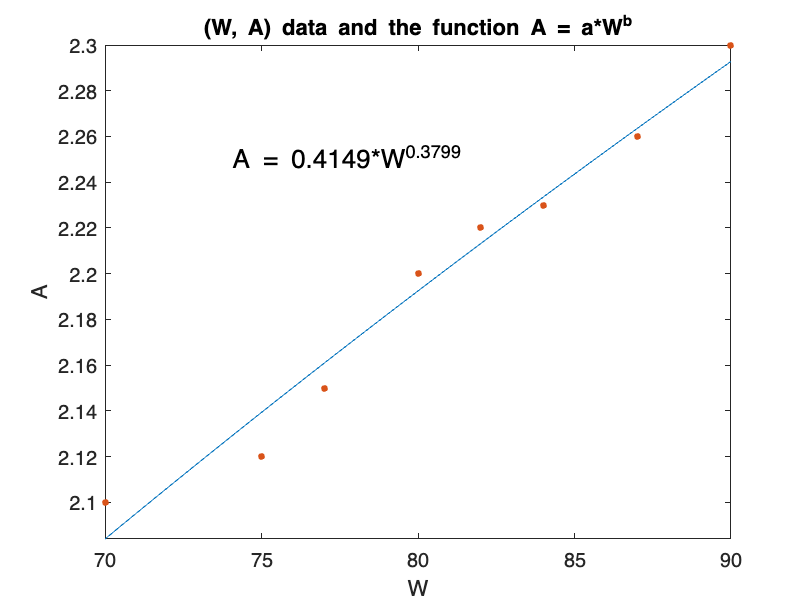

fplot(@(W) a.*(W.^C(2)))
hold on
plot(W_data, A_data, '.', 'markersize', 10)
xlim([W_data(1),W_data(m)]);
title('(W, A) data and the function A = a*W^b');
xlabel('W'); ylabel('A');
text(74,2.25,'A = 0.4149*W^{0.3799}','fontsize',13);
hold off